# The App Container Framework

This document aims to provide a brief overview of the App Container Framework. This is the internal framework for creating toolstrip-based applications shipping with various toolboxes.

## Internal packages comprising the framework.

The App Container Framework already ships with MATLAB, but is not documented for public use. Consequently all of the functionality lies in internal packages.

Use the following import statements at the start of a function to access the framework's functionality.

The current installation folders for these components can be accessed as follows. Note that these locations may change without warning between MATLAB releases. The internal package naming conventions may also be modified without warning.

## Internal class documentation.

Currently, there is no formal documentation for the classes comprising the App Container Framework. 

However, most class definitions contain helpful comments and some short code examples. To inspect the properties and methods of a class, and read any code examples that are part of the help text, open the file in the MATLAB Editor.

For example, to inspect the source code for the `AppContainer` class, enter:

edit matlab.ui.container.internal.AppContainer

Other helpful commands can be used to display the class-level documentation, properties, methods, and all class metadata for a specific class.

### Class-level documentation.

doc matlab.ui.container.internal.AppContainer

### Class properties.

properties( "matlab.ui.container.internal.AppContainer" )

### Class methods.

methods( "matlab.ui.container.internal.AppContainer" )

### All class metadata.

info = ?matlab.ui.container.internal.AppContainer

Equivalent syntax:

% info = metaclass( "matlab.ui.container.internal.AppContainer" )

## The `AppContainer` object.

The top-level graphics object in this context is an `AppContainer` object (c.f., a traditional MATLAB app, which has a `figure` or `uifigure` as its top-level object).

### Code example.

Import the required internal package.

import matlab.ui.container.internal.* 

Define a structure of options.

opts.Title = "Example App"; 

Create the `AppContainer`, returning a handle for later reference.

app = AppContainer( opts ); 

Render the app.

app.Visible = true;

**Notes** 

- The app is not made visible by default. The intended workflow is to create the app, add all of its components, then finally render the app visible. 

- Some components may error or not render correctly if the app is prematurely made visible.

- The app is equipped with a toolstrip, which can be expanded or collapsed interactively.

### Deleting the app.

To destroy the underlying app object, use the `delete` method.

delete( app )
isvalid( app ) % False

## Customizing the app's toolstrip.

The App Container Framework provides a rich set of components and APIs for creating a custom toolstrip. The toolstrip is intended to make it easy to navigate the app and simplify end-user workflows.

### Containers in the toolstrip hierarchy.

- [matlab.ui.internal.toolstrip.Toolstrip](matlab: doc matlab.ui.internal.toolstrip.Toolstrip) (top-level toolstrip ancestor - already added to the app container object)

- [matlab.ui.internal.toolstrip.TabGroup](matlab: doc matlab.ui.internal.toolstrip.TabGroup) (tab groups are added directly to the main app via [addTabGroup](matlab: edit matlab.ui.container.internal.AppContainer/addTabGroup))

- [matlab.ui.internal.toolstrip.Tab](matlab: doc matlab.ui.internal.toolstrip.Tab) (tabs are added to the tab group via [add](matlab: edit matlab.ui.internal.toolstrip.TabGroup/add))

- [matlab.ui.internal.toolstrip.Section](matlab: doc matlab.ui.internal.toolstrip.Section) (sections are added to tabs via [addSection](matlab: edit matlab.ui.internal.toolstrip.Tab/addSection))

- [matlab.ui.internal.toolstrip.Column](matlab: doc matlab.ui.internal.toolstrip.Column) (columns are added to sections via [addColumn](matlab: edit matlab.ui.internal.toolstrip.Section/addColumn))

- [matlab.ui.internal.toolstrip.Panel](matlab: doc matlab.ui.internal.toolstrip.Panel) (panels are added to columns via [add](matlab: edit matlab.ui.internal.toolstrip.Column/add))

### Helper classes available for the toolstrip.

- [matlab.ui.internal.toolstrip.EmptyControl](matlab: doc matlab.ui.internal.toolstrip.EmptyControl) (placeholder)

- [matlab.ui.internal.toolstrip.Icon](matlab: doc matlab.ui.internal.toolstrip.Icon) (used to specify an icon for various controls - both built-in and user-specified icons are possible)

- [matlab.ui.internal.toolstrip.Label](matlab: doc matlab.ui.internal.toolstrip.Label) (static control, similar to [uilabel](matlab: doc uilabel))

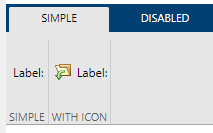

### Classes for creating a gallery within the toolstrip.

- [matlab.ui.internal.toolstrip.Gallery](matlab: doc matlab.ui.internal.toolstrip.Gallery)

- [matlab.ui.internal.toolstrip.GalleryCategory](matlab: doc matlab.ui.internal.toolstrip.GalleryCategory)

- [matlab.ui.internal.toolstrip.GalleryItem](matlab: doc matlab.ui.internal.toolstrip.GalleryItem)

- [matlab.ui.internal.toolstrip.GalleryPopup](matlab: doc matlab.ui.internal.toolstrip.GalleryPopup)

- [matlab.ui.internal.toolstrip.DropDownGalleryButton](matlab: doc matlab.ui.internal.toolstrip.DropDownGalleryButton)

- [matlab.ui.internal.toolstrip.ToggleGalleryItem](matlab: doc matlab.ui.internal.toolstrip.ToggleGalleryItem)

### Standard controls available for the toolstrip.

- [matlab.ui.internal.toolstrip.Button](matlab: doc matlab.ui.internal.toolstrip.Button) (pushbutton with optional icon and text)

- [matlab.ui.internal.toolstrip.ButtonGroup](matlab: doc matlab.ui.internal.toolstrip.ButtonGroup) (use to organize a group of radio or toggle buttons)

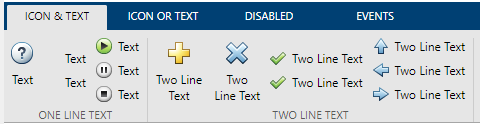

- [matlab.ui.internal.toolstrip.CheckBox](matlab: doc matlab.ui.internal.toolstrip.CheckBox)

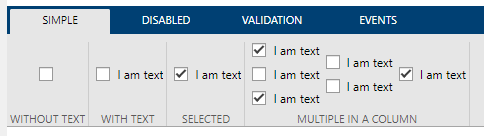

- [matlab.ui.internal.toolstrip.DropDown](matlab: doc matlab.ui.internal.toolstrip.DropDown)

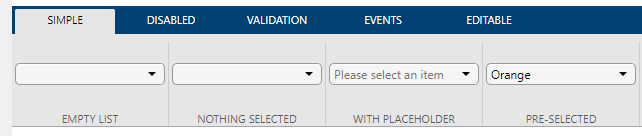

- [matlab.ui.internal.toolstrip.DropDownButton](matlab: doc matlab.ui.internal.toolstrip.DropDownButton)

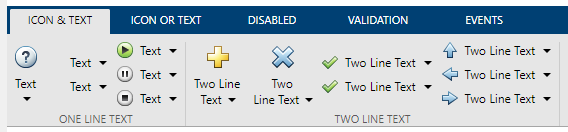

- [matlab.ui.internal.toolstrip.EditField](matlab: doc matlab.ui.internal.toolstrip.EditField)

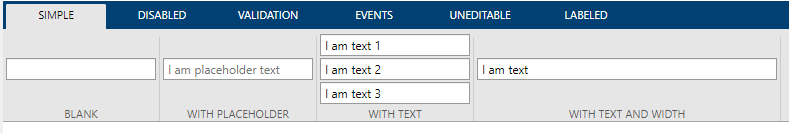

- [matlab.ui.internal.toolstrip.ListBox](matlab: doc matlab.ui.internal.toolstrip.ListBox)

- [matlab.ui.internal.toolstrip.ListItem](matlab: doc matlab.ui.internal.toolstrip.ListItem)

- [matlab.ui.internal.toolstrip.ListItemWithCheckBox](matlab: doc matlab.ui.internal.toolstrip.ListItemWithCheckBox)

- [matlab.ui.internal.toolstrip.ListItemWithEditField](matlab: doc matlab.ui.internal.toolstrip.ListItemWithEditField)

- [matlab.ui.internal.toolstrip.ListItemWithPopup](matlab: doc matlab.ui.internal.toolstrip.ListItemWithPopup)

- [matlab.ui.internal.toolstrip.ListItemWithRadioButton](matlab: doc matlab.ui.internal.toolstrip.ListItemWithRadioButton)

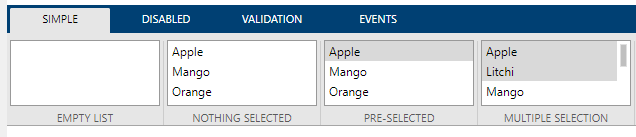

- [matlab.ui.internal.toolstrip.PopupList](matlab: doc matlab.ui.internal.toolstrip.PopupList)

- [matlab.ui.internal.toolstrip.PopupListHeader](matlab: doc matlab.ui.internal.toolstrip.PopupListHeader)

- [matlab.ui.internal.toolstrip.PopupListPanel](matlab: doc matlab.ui.internal.toolstrip.PopupListPanel)

- [matlab.ui.internal.toolstrip.PopupListSeparator](matlab: doc matlab.ui.internal.toolstrip.PopupListSeparator)

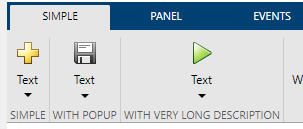

- [matlab.ui.internal.toolstrip.RadioButton](matlab: doc matlab.ui.internal.toolstrip.RadioButton)

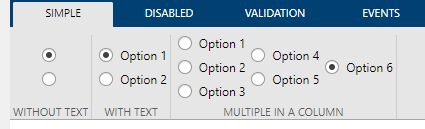

- [matlab.ui.internal.toolstrip.Slider](matlab: doc matlab.ui.internal.toolstrip.Slider)

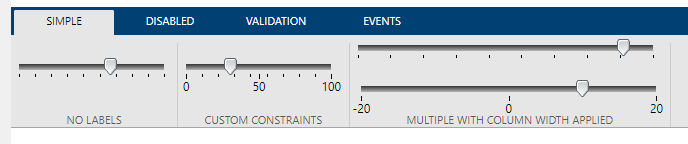

- [matlab.ui.internal.toolstrip.Spinner](matlab: doc matlab.ui.internal.toolstrip.Spinner)

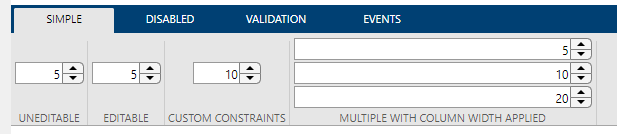

- [matlab.ui.internal.toolstrip.SplitButton](matlab: doc matlab.ui.internal.toolstrip.SplitButton)

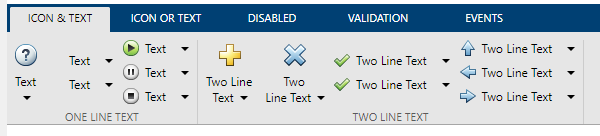

- [matlab.ui.internal.toolstrip.TextArea](matlab: doc matlab.ui.internal.toolstrip.TextArea)

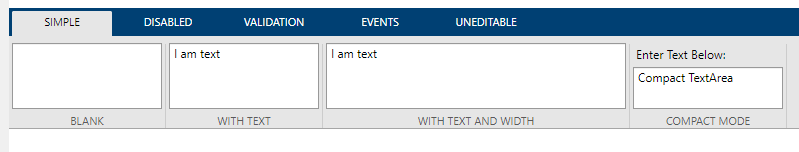

- [matlab.ui.internal.toolstrip.ToggleButton](matlab: doc matlab.ui.internal.toolstrip.ToggleButton)

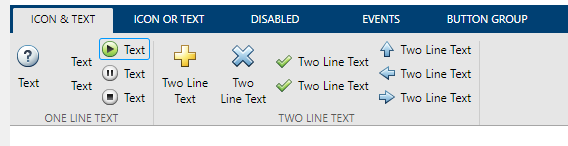

- [matlab.ui.internal.toolstrip.ToggleSplitButton](matlab: doc matlab.ui.internal.toolstrip.ToggleSplitButton)

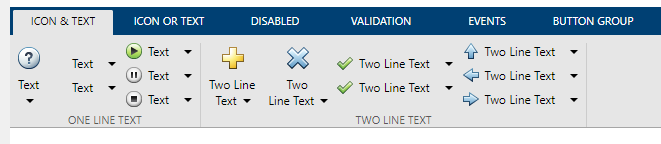

Adding multiple buttons in a row is done via panel:

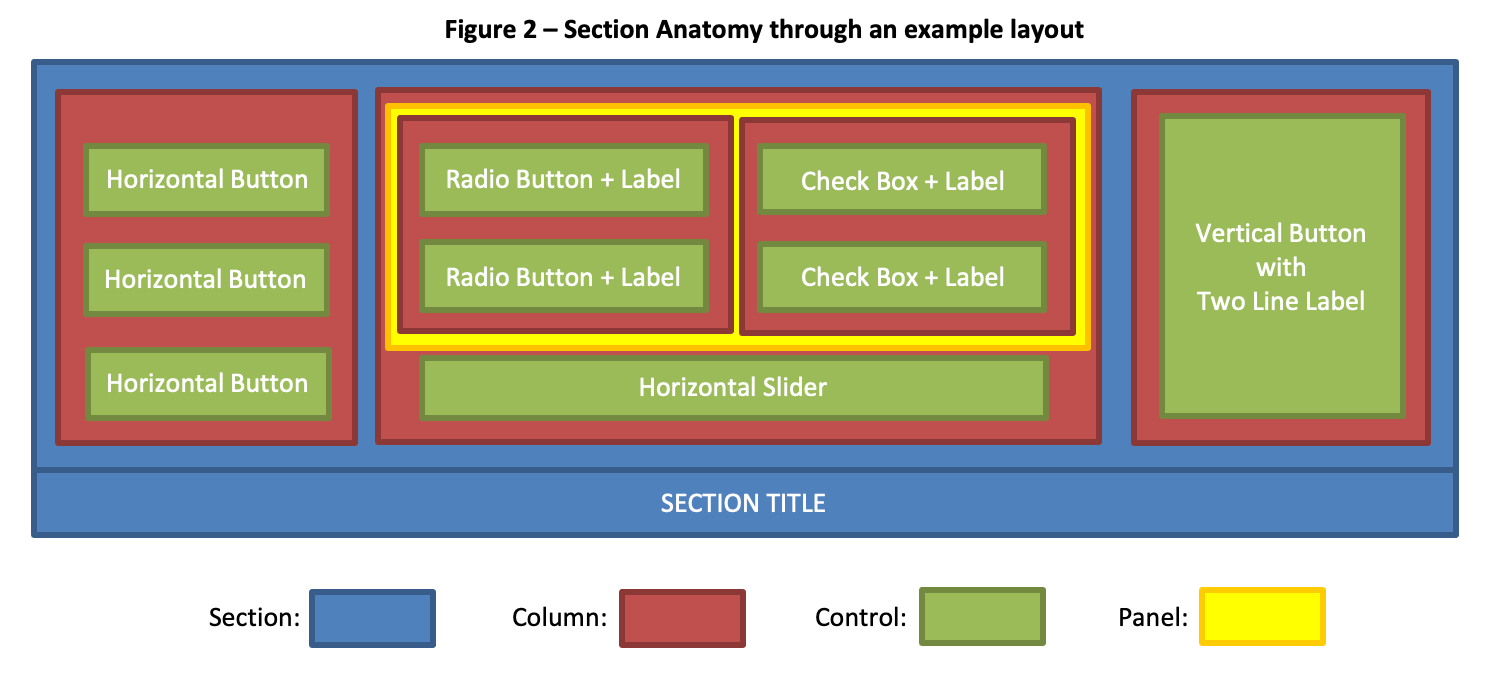

%% ============= Make "Multiple buttons in a row =============
section = obj.handles.controlsTab.addSection("Panel buttons");
column = section.addColumn('Width', 120);
panel = matlab.ui.internal.toolstrip.Panel();

% add the first column of buttons
panelColumn = panel.addColumn();
button1 = matlab.ui.internal.toolstrip.Button("",  matlab.ui.internal.toolstrip.Icon.CLEAR_16);
button1.Description = 'CLEAR_16';
panelColumn.add(button1);

button1 = matlab.ui.internal.toolstrip.Button("",  matlab.ui.internal.toolstrip.Icon.CLOSE_16);
button1.Description = 'CLOSE_16';
panelColumn.add(button1);

button1 = matlab.ui.internal.toolstrip.Button("",  matlab.ui.internal.toolstrip.Icon.CLOSE_16);
button1.Description = 'CLOSE_16';
panelColumn.add(button1);

% add the second column
panelColumn2 = panel.addColumn();
button1 = matlab.ui.internal.toolstrip.Button("",  matlab.ui.internal.toolstrip.Icon.CONFIRM_16);
button1.Description = 'CONFIRM_16';
panelColumn2.add(button1);

button1 = matlab.ui.internal.toolstrip.Button("",  matlab.ui.internal.toolstrip.Icon.CONTINUE_16);
button1.Description = 'CONTINUE_16';
panelColumn2.add(button1);

button1 = matlab.ui.internal.toolstrip.Button("",  matlab.ui.internal.toolstrip.Icon.CONTINUE_MATLAB_16);
button1.Description = 'CONTINUE_MATLAB_16';
panelColumn2.add(button1);

column.add(panel);

## Customizing the Quick Access Bar.

The quick access bar is an integral part of the main app container. It is intended to hold common shortcuts and actions, e.g., copy/cut/paste, undo/redo, open/load/save. The set of controls available for the quick access bar is more limited than for the main toolstrip.

For each of the controls below, use the [add](matlab: edit matlab.ui.container.internal.AppContainer/add) method of the app container to add them to the Quick Access Bar.

- [matlab.ui.internal.toolstrip.qab.QABHelpButton](matlab: doc matlab.ui.internal.toolstrip.qab.QABHelpButton)

- [matlab.ui.internal.toolstrip.qab.QABPushButton](matlab: doc matlab.ui.internal.toolstrip.qab.QABPushButton)

- [matlab.ui.internal.toolstrip.qab.QABRedoButton](matlab: doc matlab.ui.internal.toolstrip.qab.QABRedoButton)

- [matlab.ui.internal.toolstrip.qab.QABUndoButton](matlab: doc matlab.ui.internal.toolstrip.qab.QABUndoButton)

- [matlab.ui.internal.toolstrip.impl.QABDropDownButton](matlab: doc matlab.ui.internal.toolstrip.impl.QABDropDownButton)

- [matlab.ui.internal.toolstrip.impl.QABPushButton](matlab: doc matlab.ui.internal.toolstrip.impl.QABPushButton)

- [matlab.ui.internal.toolstrip.impl.QABSplitButton](matlab: doc matlab.ui.internal.toolstrip.impl.QABSplitButton)

- [matlab.ui.internal.toolstrip.impl.QABToggleButton](matlab: doc matlab.ui.internal.toolstrip.impl.QABToggleButton)

- [matlab.ui.internal.toolstrip.impl.QABToggleSplitButton](matlab: doc matlab.ui.internal.toolstrip.impl.QABToggleSplitButton)

## Working with documents and panels.

Within the body of the app container app, we can add documents and panels. Documents belong to a *document group*, whereas panels can be added directly to the app container. Both documents and panels have a `Figure` property (a `uifigure`) in which standard app building components (i.e., the components available in App Designer) and graphics objects, such as axes, can be placed.

- [matlab.ui.internal.FigureDocumentGroup](matlab: doc matlab.ui.internal.FigureDocumentGroup) (container for figure documents)

- [matlab.ui.internal.FigureDocument](matlab: doc matlab.ui.internal.FigureDocument) (should be parented to a figure document group via the `add` method)

- [matlab.ui.internal.FigurePanel](matlab: doc matlab.ui.internal.FigurePanel) 

**Notes**

- Figure panels should be anchored to the **left**, **right** or **bottom** of the app container.

- We use the `add` method to attach a figure panel to the app container.

- The document and panel superclasses [matlab.ui.container.internal.appcontainer.Document](matlab: doc matlab.ui.container.internal.appcontainer.Document) and [matlab.ui.container.internal.appcontainer.Panel](matlab: doc matlab.ui.container.internal.appcontainer.Panel), respectively, contain more information about the properties and methods of documents and panels.

## Adding and customizing a Status Bar.

The status bar appears in the footer of the app container. It can be equipped with a smaller set of controls compared to the toolstrip, and is intended for indicating the current status of the app.

The container class [matlab.ui.internal.statusbar.StatusBar](matlab: doc matlab.ui.internal.statusbar.StatusBar) supports the following children. We use the `add` method of the app container to attach the status bar to the app.

- [matlab.ui.internal.statusbar.StatusButton](matlab: doc matlab.ui.internal.statusbar.StatusButton)

- [matlab.ui.internal.statusbar.StatusEditField](matlab: doc matlab.ui.internal.statusbar.StatusEditField)

- [matlab.ui.internal.statusbar.StatusGroup](matlab: doc matlab.ui.internal.statusbar.StatusGroup)

- [matlab.ui.internal.statusbar.StatusLabel](matlab: doc matlab.ui.internal.statusbar.StatusLabel)

- [matlab.ui.internal.statusbar.StatusProgressBar](matlab: doc matlab.ui.internal.statusbar.StatusProgressBar)

- [matlab.ui.internal.statusbar.StatusToggleButton](matlab: doc matlab.ui.internal.statusbar.StatusToggleButton)

## Dialogs, alerts and progress bars.

The standard app building components for display dialogs, alerts and progress bars can be used in an App Container app. Instead of associating the component with a `uifigure`, we associate it with the app container. The first input argument should be a reference to the app container object.

- [uiconfirm](matlab: doc uiconfirm)

- [uialert](matlab: doc uialert)

- [uiprogressdlg](matlab: doc uiprogressdlg)